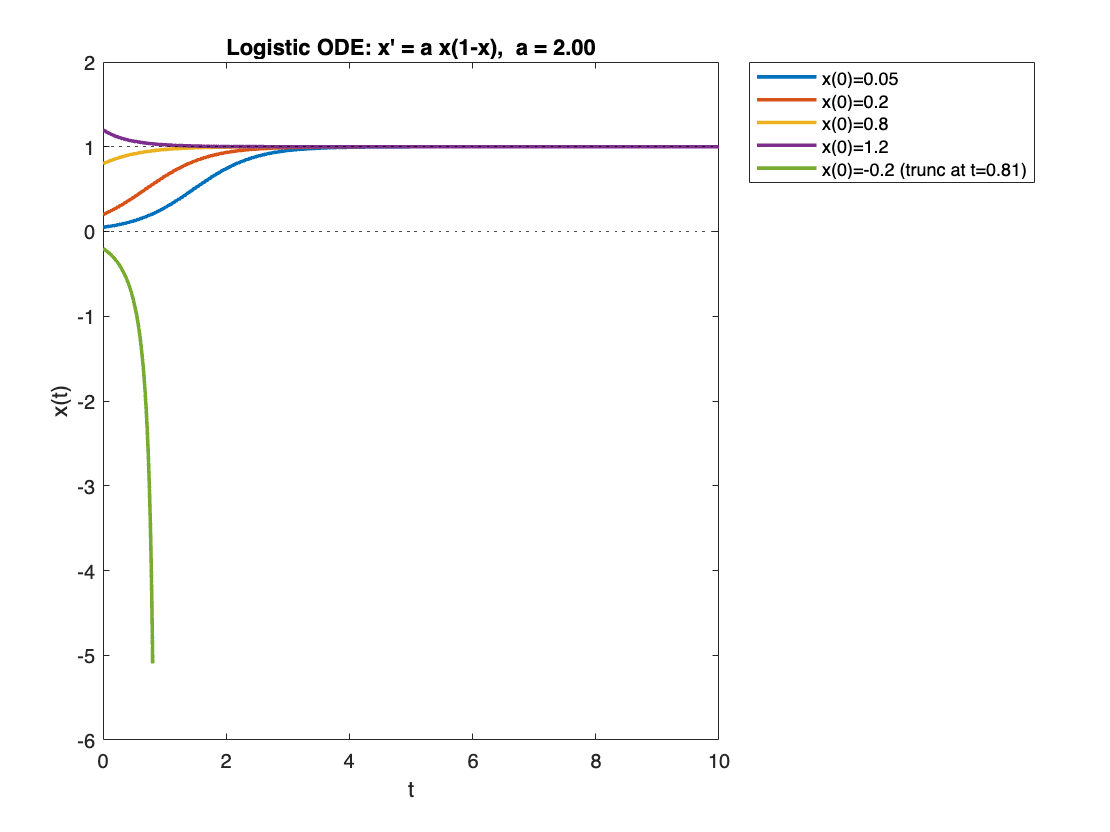

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Recitation Demo (Part 1 only):
% Numerical solving + phase-line / phase portrait for logistic model
%
% Model:  x' = a x (1 - x)
%
% Demonstrations:
%   (A) ode45 solutions for several initial conditions
%   (B) explicit Euler method solutions and comparison to ode45
%   (C) phase line (direction field on the real line)
%
% Notes:
%   - For x0 < 0, the exact solution blows up to -Inf in finite time.
%     Hence ode45 may fail if you integrate past that singularity.
%     We truncate integration at 90% of the blow-up time for negative x0.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% Parameters and model
a = 2;                      % growth rate
f = @(t,x) a*x.*(1-x);      % RHS for ode45

tmax = 10;                  % default final time for demonstrations
tspan_default = [0 tmax];

% A selection of initial conditions.
% IMPORTANT: x0 = -0.2 leads to finite-time blow-up (to -Inf).
x0_list = [0.05 0.2 0.8 1.2 -0.2];

%% (A) Numerical solutions with ode45 (with safe truncation for x0<0)
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

figure('Name','Logistic: ode45 solutions','Color','w'); hold on; box on;

legendEntries = cell(size(x0_list));
for k = 1:numel(x0_list)
    x0 = x0_list(k);

    % If x0 < 0, the solution blows up at finite time:
    % Exact solution: x(t)= x0 / ( x0 + (1-x0) e^{-a t} ).
    % Denominator crosses 0 when e^{-a t} = -x0/(1-x0) (positive for x0<0).
    % Hence blow-up time:
    %   t_blow = (1/a) * log((1-x0)/(-x0)).
    if x0 < 0
        t_blow = (1/a) * log((1 - x0)/(-x0));
        t_end = min(tmax, 0.90*t_blow);  % stop before singularity
        tspan = [0 t_end];
        legendEntries{k} = sprintf('x(0)=%.2g (trunc at t=%.2f)', x0, t_end);
    else
        tspan = tspan_default;
        legendEntries{k} = sprintf('x(0)=%.2g', x0);
    end

    % Solve
    try
        [t,x] = ode45(f, tspan, x0, opts);
        plot(t,x,'LineWidth',1.8);
    catch ME
        % If something still fails, report and skip
        warning('ode45 failed for x0=%.3g: %s', x0, ME.message);
    end
end

yline(0,'k:'); yline(1,'k:');
xlabel('t'); ylabel('x(t)');
title(sprintf('Logistic ODE: x'' = a x(1-x),  a = %.2f', a));
legend(legendEntries,'Location','bestoutside');


%% Stability check (no ternary function; use explicit if)
fp = @(x) a*(1-2*x);    % derivative of f(x)=a x(1-x) w.r.t x

fprintf('\nLogistic equilibria and stability (a=%.2f):\n', a);


Logistic equilibria and stability (a=2.00):



% Equilibrium x*=0
if fp(0) < 0
    stab0 = 'stable';
elseif fp(0) > 0
    stab0 = 'unstable';
else
    stab0 = 'degenerate (need nonlinear terms)';
end
fprintf('  x*=0:  f_x(0)=%.3g  => %s\n', fp(0), stab0);

  x*=0:  f_x(0)=2  => unstable



% Equilibrium x*=1
if fp(1) < 0
    stab1 = 'stable';
elseif fp(1) > 0
    stab1 = 'unstable';
else
    stab1 = 'degenerate (need nonlinear terms)';
end
fprintf('  x*=1:  f_x(1)=%.3g  => %s\n', fp(1), stab1);

  x*=1:  f_x(1)=-2  => stable


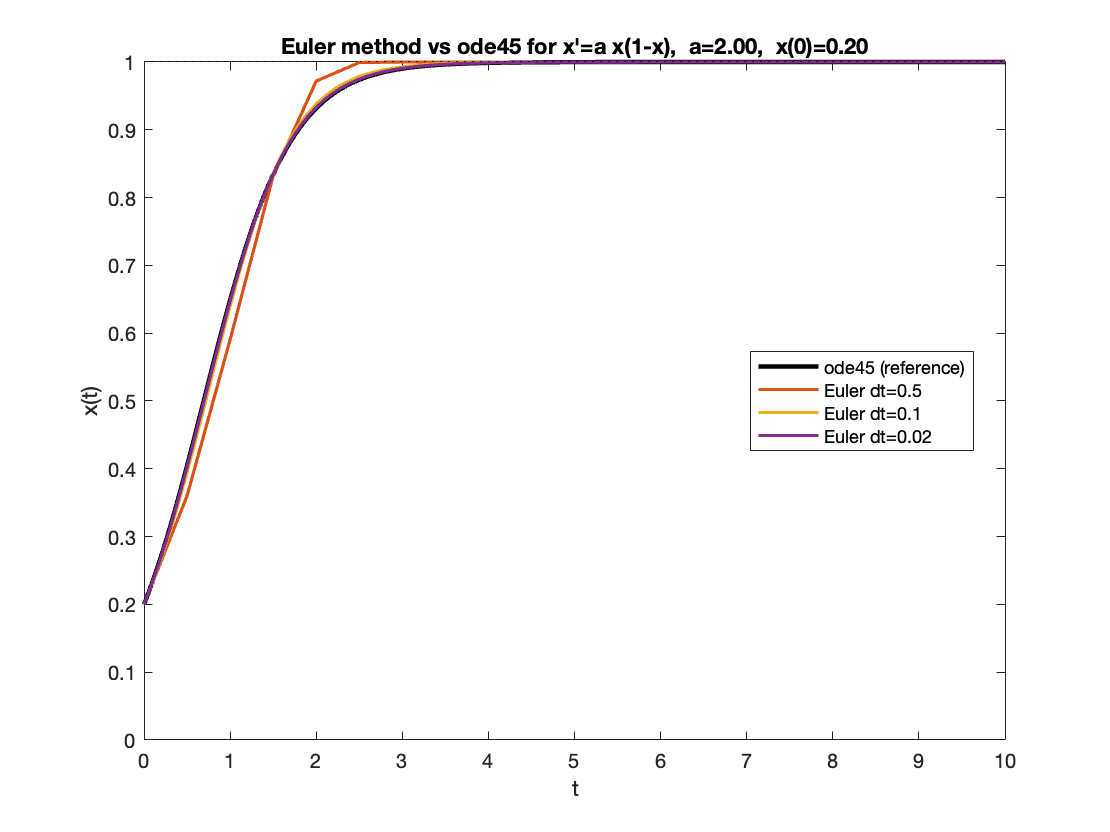


%% (B) Explicit Euler method demo + comparison with ode45
% Euler update: x_{n+1} = x_n + dt * a x_n (1 - x_n)

x0_demo = 0.2;      % choose a safe initial condition for Euler comparison
dt_list = [0.5 0.1 0.02];  % show effect of step size

figure('Name','Logistic: Euler vs ode45','Color','w'); hold on; box on;

% Reference "accurate" solution from ode45
[t_ref, x_ref] = ode45(f, [0 tmax], x0_demo, opts);
plot(t_ref, x_ref, 'k-', 'LineWidth', 2.2);
leg = {'ode45 (reference)'};

% Euler solutions for different dt
for dt = dt_list
    t = 0:dt:tmax;
    x = zeros(size(t));
    x(1) = x0_demo;

    for n = 1:(numel(t)-1)
        x(n+1) = x(n) + dt * a * x(n) * (1 - x(n));
    end

    plot(t, x, 'LineWidth', 1.6);
    leg{end+1} = sprintf('Euler dt=%.3g', dt);
end

yline(0,'k:'); yline(1,'k:');
xlabel('t'); ylabel('x(t)');
title(sprintf('Euler method vs ode45 for x''=a x(1-x),  a=%.2f,  x(0)=%.2f', a, x0_demo));
legend(leg,'Location','best');

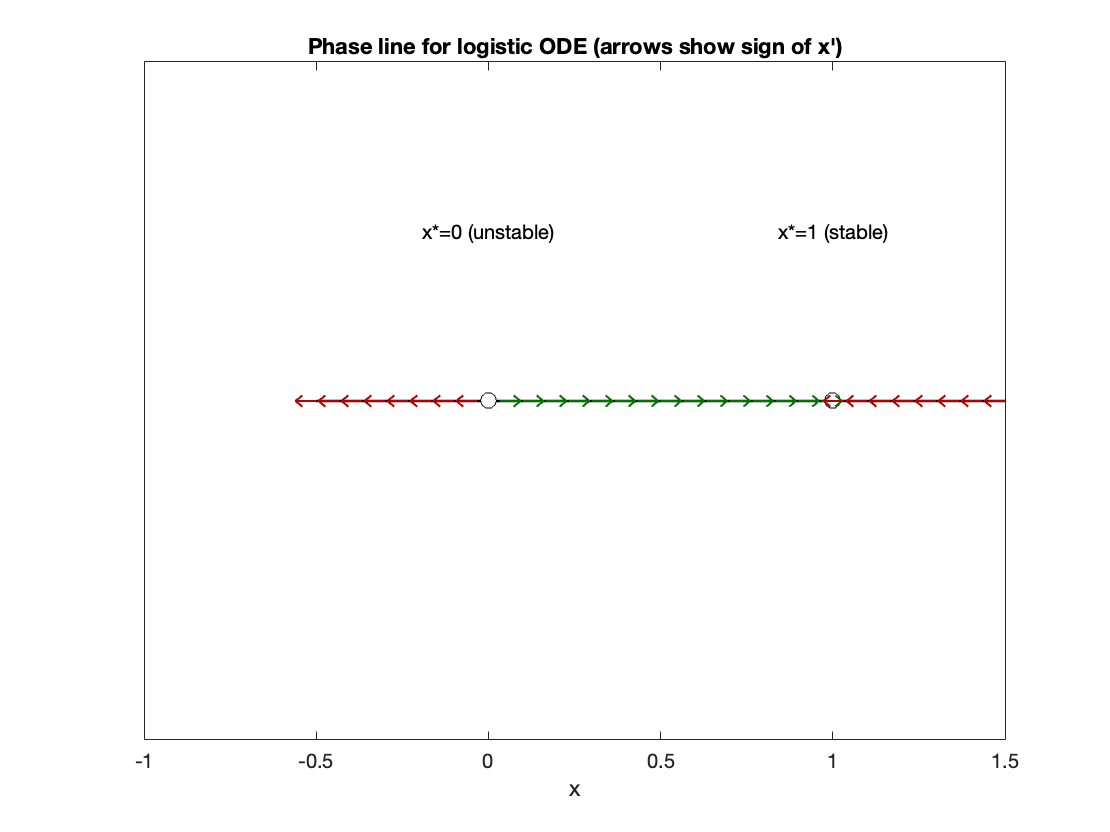


% Instructor note:
% - dt too large can cause visible numerical artifacts (overshoot, oscillation).
% - smaller dt improves agreement with ode45.

%% (C) Phase line / direction field on the real line
xgrid = linspace(-0.5, 1.5, 31);
dx = a*xgrid.*(1-xgrid);

figure('Name','Logistic: phase line','Color','w'); hold on; box on;

% Draw base line
plot([min(xgrid) max(xgrid)], [0 0], 'k-', 'LineWidth', 1.2);

% Mark equilibria
plot(0,0,'ko','MarkerFaceColor','w','MarkerSize',8);
plot(1,0,'ko','MarkerFaceColor','w','MarkerSize',8);

% Arrows indicating direction (sign of x')
for i = 1:numel(xgrid)
    if dx(i) > 0
        quiver(xgrid(i),0, 0.06,0,0,'Color',[0 0.45 0],'LineWidth',1,'MaxHeadSize',1);
    elseif dx(i) < 0
        quiver(xgrid(i),0,-0.06,0,0,'Color',[0.70 0 0],'LineWidth',1,'MaxHeadSize',1);
    end
end

ylim([-0.3 0.3]);
xlabel('x'); yticks([]);
title('Phase line for logistic ODE (arrows show sign of x'')');

% Optional: annotate stability with text
text(0, 0.15, sprintf('x*=0 (%s)', stab0), 'HorizontalAlignment','center');
text(1, 0.15, sprintf('x*=1 (%s)', stab1), 'HorizontalAlignment','center');